clear
clc
close all

## Temperature behavior

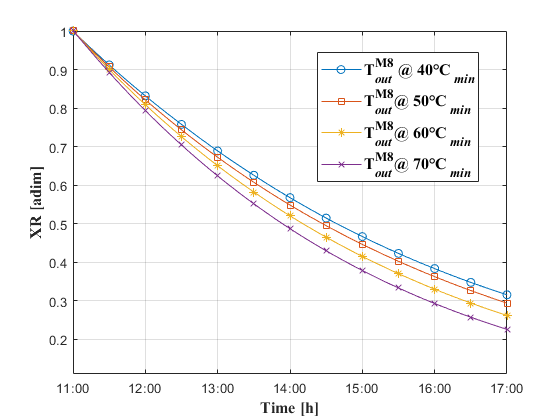

data=load('MR_T.txt');
t=data(:,1);
MR_40=data(:,2); % MR a temperatura 40°C
MR_50=data(:,3); % MR a temperatura 50°C
MR_60=data(:,4); % MR a temperatura 60°C
MR_70=data(:,5); % MR a temperatura 70°C


figure (1) %Contenido de humedad (bs) a diferentes temperaturas
ini=1;
paso=5;
plot(t,MR_40,'-o',t,MR_50,'-s',t,MR_60,'-*',t,MR_70, '-x','MarkerIndices',ini:paso:length(t));...
    xticklabels({'11:00','12:00','13:00','14:00','15:00','16:00','17:00'});
    grid on; xlabel('Time [h]','FontWeight','bold','FontSize',12,'FontName','Times New Roman');...
        ylabel('XR [adim]','FontWeight','bold','FontSize',12,'FontName','Times New Roman');...
        legend('T^{M8}_{\it{out}} @ 40°C_{\it min}','T^{M8}_{\it{out}}@ 50°C_{\it min}',...
        'T^{M8}_{\it{out}}@ 60°C_{\it min}','T^{M8}_{\it{out}}@ 70°C_{\it min}','FontWeight','bold',...
        'FontSize',12,'FontName','Times New Roman','Location',"best")
    
    xlim([11.0 17.0])
    ylim([0.110 1.00])

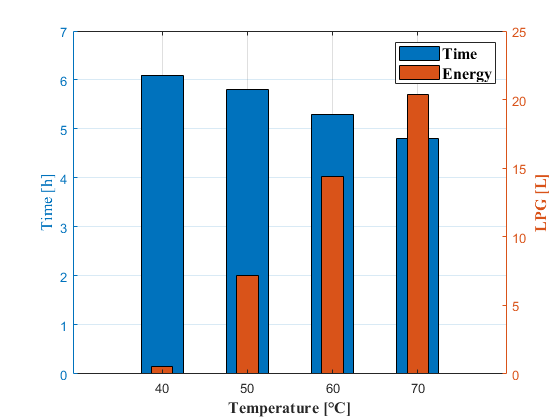

    
figure (2)
Temp = [40 50 60 70];
yyaxis left
time = [6.1 5.8 5.3 4.8];
b1=bar(Temp,time,'BarWidth',0.5);grid on; xlabel('Temperature [°C]','FontWeight','bold','FontSize',...
    12,'FontName','Times New Roman');ylabel('Time [h]','FontSize',12,'FontName','Times New Roman')
yyaxis right
LPG=[0.54 7.2 14.42 20.39];
b2=bar(Temp,LPG,'BarWidth',0.25);grid on; ylabel('LPG [L]','FontWeight','bold','FontSize',12,...
    'FontName','Times New Roman')
legend([b1 b2],'Time','Energy','FontWeight','bold','FontSize',12,'FontName','Times New Roman')

## Thermal Dynamics

data=load('Thermal_dyn.txt');
t=data(:,1);
T_DH_in=data(:,2); % Temperatura en la salida de M8
T_0INF=data(:,3); % Temperatura de salida del tunel con 0% infiltraciones
XR_0INF=data(:,4); % XR con 0% infiltraciones
T_10INF=data(:,5); % Temperatura de salida del tunel con 10% infiltracionesfan
XR_10INF=data(:,6); % XR con 10% infiltraciones
T_20INF=data(:,7); % Temperatura de salida del tunel con 20% infiltraciones
XR_20INF=data(:,8); % XR con 20% infiltraciones
T_PROD=data(:,9); % Temperatura de salida del tunel sin PRODUCTO
XR_PROD=data(:,10); % XR con sin PRODUCTO
T_SHELF=data(:,11); % Temperatura de salida del tunel sin SHELF
XR_SHELF=data(:,12); % XR con sin SHELF
ini=1;
paso=5;

figure (3) %Temperatura de salida del túnel variando 
plot(t,T_DH_in,'-o',t,T_0INF,'-s',t,T_10INF,'-*',t,T_20INF,'-x',t,T_PROD,'-d',t,T_SHELF,'-p','MarkerIndices',ini:paso:length(t));...
    xticklabels({'','12:00','13:00','14:00','15:00','16:00','17:00'});...
    grid on; xlabel('Time [h]','FontWeight','bold','FontSize',12,'FontName','Times New Roman');...
        ylabel('Temperature [°C]','FontWeight','bold','FontSize',12,'FontName','Times New Roman');...
        legend('T^{M8}_{\it{out}}','T^{DH1}_{\it{out}}{\it 0% INF}','T^{DH1}_{\it{out}}{\it 10% INF}',...
        'T^{DH1}_{\it{out}}{\it 20% INF}','T^{DH1}_{\it{out}}{\it PROD}','T^{DH1}_{\it{out}}{\it SHELF}',...
        'FontWeight','bold','FontSize',12,'FontName','Times New Roman','Location',"best")


## Mass behavior

data=load('Mass_behavior.txt');
t=data(:,1);
% Temperatura en la salida de M8
T_DH_out_05=data(:,4);
T_DH_out_103=data(:,14);
T_DH_out_180=data(:,24);
RH_DH_out_05=data(:,6)*100;
RH_DH_out_103=data(:,16)*100;
RH_DH_out_180=data(:,26)*100;

ini=1;
paso=5;

figure (4) %Temperatura de salida del túnel variando 
yyaxis left
plot(t,T_DH_out_05,'-','MarkerIndices',ini:paso:length(t))
hold on
plot(t,T_DH_out_103,':','MarkerIndices',ini:paso:length(t),'LineWidth',2)
plot(t,T_DH_out_180,'--','MarkerIndices',ini:paso:length(t));grid on; ...
    xlabel('Time [h]','FontWeight','bold','FontSize',12,'FontName','Times New Roman');...
    ylabel('Temperature [°C]','FontWeight','bold','FontSize',12,'FontName','Times New Roman')
hold off

yyaxis right
plot(t,RH_DH_out_05,'-','MarkerIndices',ini:paso:length(t));
hold on
plot(t,RH_DH_out_103,':','MarkerIndices',ini:paso:length(t),'LineWidth',2);
plot(t,RH_DH_out_180,'--','MarkerIndices',ini:paso:length(t));...
    xticklabels({'','12:00','13:00','14:00','15:00','16:00','17:00'});grid on; ...
    xlabel('Time [h]','FontWeight','bold','FontSize',12,'FontName','Times New Roman');...
    ylabel('Relative Humidity [%]','FontWeight','bold','FontSize',12,'FontName','Times New Roman');...
    legend('T{\it @0.5kg/s}','T{\it @1.03kg/s}','T{\it @1.80kg/s}','RH{\it @0.5kg/s}',...
    'RH{\it @1.03kg/s}','RH{\it @1.80kg/s}','FontWeight','bold','FontSize',12,'FontName',...
    'Times New Roman','Location',"northeast")
    
hold off

% figure (4) %Temperatura de salida del túnel variando 
% yyaxis left
% plot(t,T_DH_in_05,'-o',t,T_DH_in_103,'-s',t,T_DH_in_180,'-*',...
%     'MarkerIndices',ini:paso:length(t));grid on; xlabel('Time [h]');ylabel('Temperature [°C]');...
% 
% yyaxis right
% plot(t,RH_DH_in_05,'-o',t,RH_DH_in_103,'-sk',t,RH_DH_in_180,'-*',...
%     'MarkerIndices',ini:paso:length(t));grid on; xlabel('Time [h]');ylabel('Relative Humidity [%]');...
%     legend('T^{M8}_{\it{out}}{\it @0.5kg/s}','T^{M8}_{\it{out}}{\it @1.03kg/s}',...
%     'T^{M8}_{\it{out}}{\it @1.80kg/s}','RH{\it @0.5kg/s}','RH{\it @1.03kg/s}','RH{\it @1.80kg/s}',...
%     'Location',"northeast")

data=load('MassFlowMR.txt');
t=data(:,1);
% Temperatura en la salida de M8
MR_05=data(:,2);
MR_103=data(:,3);
MR_180=data(:,4);

ini=1;
paso=5;

figure (5)
plot(t,MR_05,'-k','MarkerIndices',ini:paso:length(t));

hold on
plot(t,MR_103,':k','MarkerIndices',ini:paso:length(t),'LineWidth',2);
plot(t,MR_180,'--k','MarkerIndices',ini:paso:length(t));
    xticklabels({'','12:00','13:00','14:00','15:00','16:00','17:00'});...
    grid on; xlabel('Time [h]','FontWeight','bold','FontSize',12,'FontName','Times New Roman');...
        ylabel('XR [adim]','FontSize',12,'FontName','Times New Roman');...
        legend('XR{\it @0.5kg/s}','XR{\it @1.03kg/s}','XR{\it @1.80kg/s}','FontWeight','bold',...
        'FontSize',12,'FontName','Times New Roman','Location',"northeast")
hold off

% MR(1,:)=MR_05;
% MR(2,:)=MR_103;
% MR(3,:)=MR_180;
% createfigure(MR,t)

## XR Comparisson

data=load('XR_EXP.txt');
t_EXP=data(:,1);
XR_EXP=data(:,2);
data=load('XR_SIM.txt');
t_SIM=data(:,1);
XR_SIM=data(:,2);

figure (6)

plot(t_EXP,XR_EXP,'.',t_SIM,XR_SIM);grid on; xlabel('Time [h]','FontWeight','bold','FontSize',12,...
    'FontName','Times New Roman');ylabel('XR [adim]','FontSize',12,'FontName','Times New Roman');...
    legend('XR_{exp}','XR_{sim}','FontWeight','bold','FontSize',12,'FontName',...
    'Times New Roman','Location',"northeast")
xlim([11.00 17.00])
ylim([0.300 1.000])

xticklabels({'','12:00','13:00','14:00','15:00','16:00','17:00'});

## Tunnel temperature comparisson

data=load('ExpTunnelTemp.txt');
t_EXP=data(:,1);
T_in_EXP=data(:,2);
T_out_EXP=data(:,3);
data=load('SimTunnelTemp.txt');
t_SIM=data(:,1);
T_in_SIM=data(:,2);
T_out_SIM=data(:,3);

figure (7)

plot(t_EXP,T_in_EXP,'.',t_EXP,T_out_EXP,'.','MarkerIndices',ini:paso:length(t_EXP));...
    xticklabels({'','12:00','13:00','14:00','15:00','16:00','17:00'});...
    grid on; xlabel('Time [h]','FontWeight','bold','FontSize',12,'FontName','Times New Roman');...
        ylabel('Temperature [°C]','FontSize',12,'FontName','Times New Roman');
    
hold on
plot(t_SIM,T_in_SIM,t_SIM,T_out_SIM);grid on; xlabel('Time [h]','FontWeight','bold',...
    'FontSize',12,'FontName','Times New Roman');ylabel('Temperature [°C]','FontWeight','bold',...
    'FontSize',12,'FontName','Times New Roman'); legend('T^{M8}_{\it out,exp}',...
    'T^{DH1}_{\it exp}','T^{M8}_{\it out,sim}','T^{DH1}_{\it out,sim}','FontWeight','bold',...
    'FontSize',12,'FontName','Times New Roman','Location',"southeast")